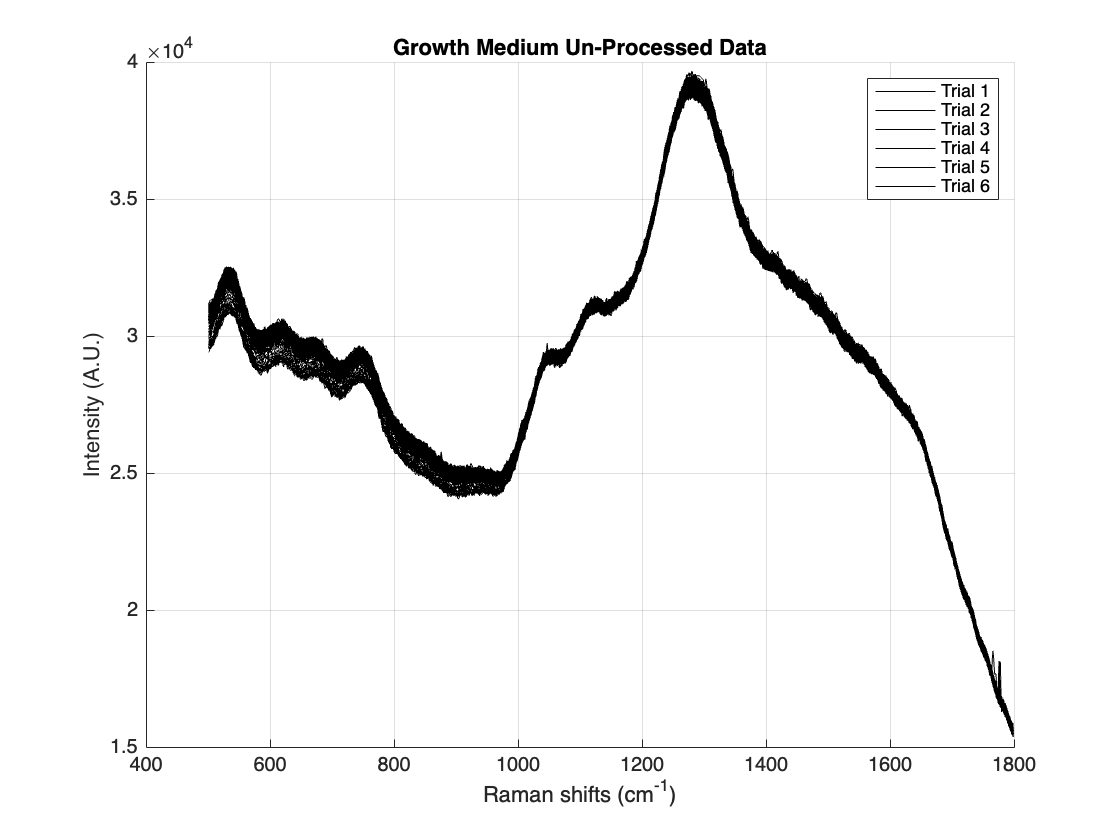

% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-07-05/";


% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

file_name = "Growth(20x,495mW)_1750_200_2024-07-05-16.05.32.317.csv";
file_path = data_path+file_name;
growth_1 = csvread(file_path, numMetadataRows, 0);

fulldata = readmatrix('Data/Training_Compact_May_2023.csv');
n = 10; % donor number
% 10 donors donor ID's
% D1-186 D2-191 D3-102 D4-86 D5-192 D8-77 D9-195 D10-123 D11-196 D12-197
don = [186, 191, 102, 86, 192, 77, 195, 123, 196, 197];
 
% trimming blood plasma data and standard samples data to these WN's
t1 = 500;
t2 = 1800;

wavenumber = growth_1(1,:);

data_1 = fulldata;  
data_1(:, data_1(1, :) <= t1) = [];
data_1(:, data_1(1, :) >= t2) = [];
data_1 = [[fulldata(:, 1:3)] data_1];
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
growth_1(:, growth_1(1, :) <= t1) = [];
growth_1(:, growth_1(1, :) >= t2) = [];

grow1 = growth_1(2:end, :);
shifts = data_1(1, 4:end);

% import standard sample data and take average to use for Raman shift
% correction and NIST correction
poly1 = readmatrix('Data/Polystyrene_1_2024-05-07-10.40.30.583.csv'); 
poly = mean(poly1(2:end,:));

Si1 = readmatrix('Data/Silicon_2_2024-05-07-10.25.23.800.csv'); 
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];
std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

nist1 = readmatrix('Data/NIST_0823_120523_2023-05-12-08.23.54.csv');
NISTspectrum = [fulldata(1, 4:end) ; nist1(23:end, :)];
NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

figure;
hold on;
grid on;
plot(wavenumber, grow1, '-k');
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Growth Medium Un-Processed Data');
hold off;


% PREPROCESSING THE DATA
[all, train, test] = prepSet(data_1, don(n), -1, -1, [6,1,10,11,8,2,5,6,7]);
prep = [0 0 0 shifts ;  all];
pro_grow1 = apply(grow1, [6,1,10,11,8,2,5,6,7]);

% PLOTS OF THE RAW AND PREPROCESSED DATA
fig1 = figure;
ax1 = axes(fig1);
hold on;
plot(ax1, shifts, data_1(data_1(:, 2) == 0, 4:end), 'b')
% plot(ax1, shifts, data_1(data_1(:, 2) == 5, 4:end), 'r')
% plot(ax1, shifts, data_1(data_1(:, 2) == 20, 4:end), 'g')
xlabel(ax1, 'Raman shifts (cm^{-1})')
ylabel(ax1, 'Intensity (A.U.)')
title('Growth Medium Raw Data')
ax1.FontSize = 18;
hold off;

figure;
hold on;
plot(shifts, all(all(:, 2) == 1, 4:end), 'b')
% plot(shifts, all(all(:, 2) == 6, 4:end), 'r')
% plot(shifts, all(all(:, 2) == 21, 4:end), 'g')
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')

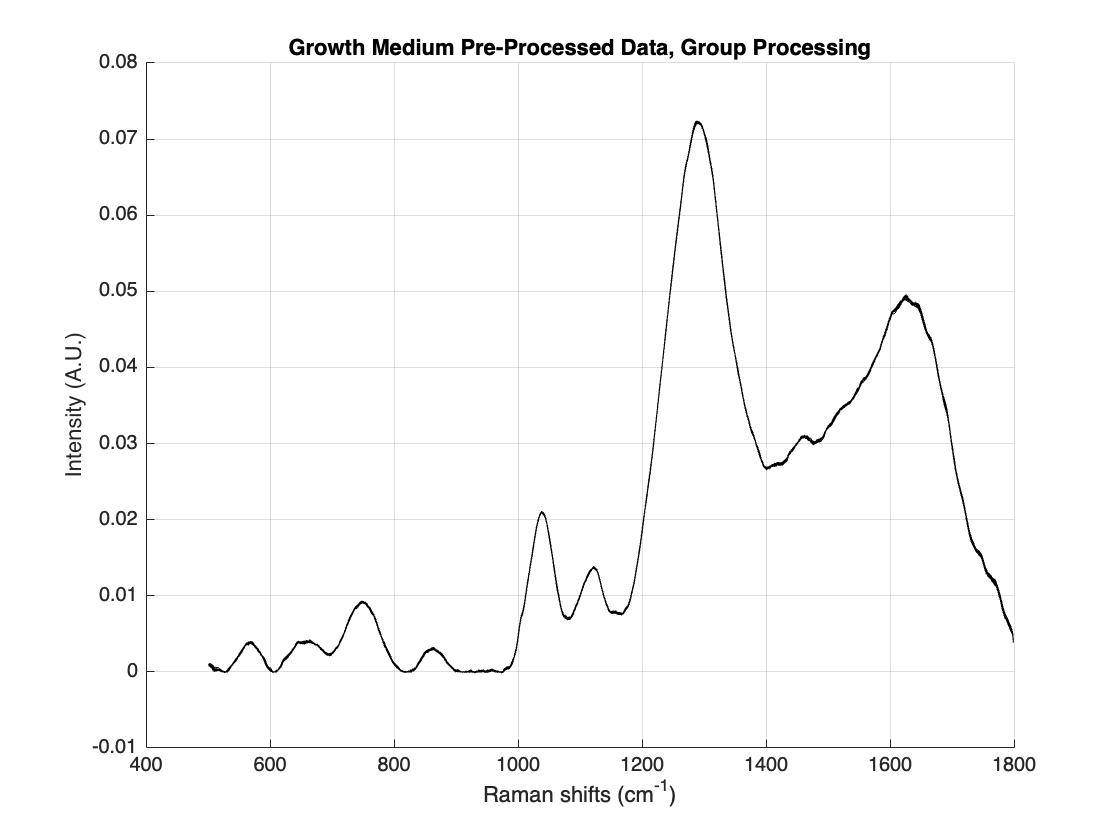

figure;
hold on;
grid on;
plot(wavenumber, pro_grow1, '-k');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data, Group Processing');
hold off;


% Save pre-processed data as a CSV file

%csvwrite('spectra_sample.csv', prep );


function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end
